## SEMTM0010 Transport and Mobility Modelling

### Labsheet: Data-driven modelling

Nikolai Bode

This labsheet will guide you through examples related to the content covered in the four topics on data-driven modelling, and suggest follow-on exercises. Solutions to the exercises are not provided. The purpose of the lab is to give you the opportunity to test and discuss your thinking on answering the exercises.

The labsheet containes three main sections:

- Example for direct demand modelling

- Examples for time-series modelling

- Example for data-driven microscopic modelling

The first two sections use the same data on hourly pedestrian counts in the city of Mebourne, Australia. You can find more information about this data here: [https://www.pedestrian.melbourne.vic.gov.au/#date=16-09-2024&time=23](https://www.pedestrian.melbourne.vic.gov.au/#date=16-09-2024&time=23) 

The final section uses different data that is explained below.

For the purpose of this lab, all the data wrangling has been done for you, and you can get all the data you need from files that you can download from Blackboard.

### 1. Direct demand modelling

In this example, we will be implementing a very simple direct demand modelling approach on pedestrian counts. Using inverse distance weighting (as discussed in lectures), we will interpolate between observed counts as a way of predicting counts, e.g. at unobserved locations. Of course this is only one example for direct demand models. This section serves as an introduction to this modelling approach. The exercises at the end of this section will prompt you to think about developing the model further, and the data is a good testbed for trying out the other direct demand modelling approaches covered in lectures.

The data for the first two sections and how to read it into Matlab is explained below:

% read in data from pedestrian counters
% hourly counts for 13 counters for 52 days in June and July 2019.
central = readmatrix('pedestrian_counts.txt');
% remove first columns (these are the location names which are converted
% into NaNs by matlab)
central = central(:,2:1249);

% read in xy cooordinates for line segments that define the road network
% for the central part of Melbourne investigated here
% (in arbitrary units that could be rescaled to metres)
xs = load('lines_xs.txt');
ys = load('lines_ys.txt');
ys = 655 - ys; % this resetting of y-values is just for plotting purposes
%... usually, you would have to obtain these line segments from mapping
%tools, e.g. Open Street Maps.

% read in sensor xy coordinates (in arbitrary units that could be rescaled to metres)
sensx = load('sensors_xs.txt');
sensy = load('sensors_ys.txt');
%sensy = 655 - sensy; % this resetting of y-values is just for plotting purposes

Let's plot the road data and sensor locations, so that we can get a sense of what it looks like:

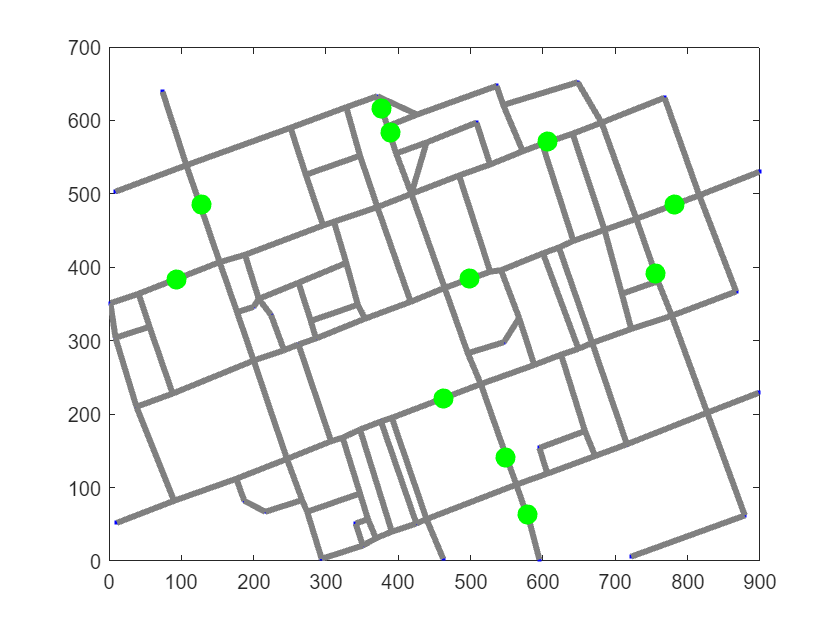

% Plot the x and y coordinates
figure;
plot(xs, ys, 'b.');  % Plot as points (black dots)
hold on;

% Get number of line segments
n = length(xs) / 2;

% Loop through and plot each line segment
for i = 1:n
    % Color of the segment (grey)
    coll = [0.5, 0.5, 0.5]; % RGB for grey

    % Plot line segment with specified color and width
    line([xs(2*i-1), xs(2*i)], [ys(2*i-1), ys(2*i)], 'Color', coll, 'LineWidth', 3);
end

% Show sensor locations as green points
scatter(sensx, sensy, 100, 'g', 'filled'); % Size 100, color green, filled circles

hold off;

We won't look at the pedestrian counts in much detail for now, as we will revisit this in section 2.

The plan for our approach can be summarise as follows:

- define a weighted network based on the street segments where nodes correspond to street segments, links indicate if segments are directly connected and weights correspond to the distance between street segment midpoints

- assign sensor locations to the nearest street segment, merging counts from sensors that are assigned to the same links

- compute the shortest distances between all nodes and all sensor locations

- use inverse distance weighting to predict counts on nodes based on observed counts

We'll now go through each of these steps in turn.

% Convert street segments to network

% Initialize adjacency matrix
n = length(xs) / 2;
A = zeros(n, n);

% Calculate adjacency matrix
% the specifics of this are down to the format of the files
% edges indicate that two road segments are directly connected.
% the weight is 1/2 of both road segment lengths added together.
for i = 1:n
    for j = i:n
        if i ~= j
            % here we check if the two road segments share a start/end
            % coordinate
            xdiff = abs([xs(2*i-1)-xs(2*j-1), xs(2*i-1)-xs(2*j), xs(2*i)-xs(2*j-1), xs(2*i)-xs(2*j)]);
            ydiff = abs([ys(2*i-1)-ys(2*j-1), ys(2*i-1)-ys(2*j), ys(2*i)-ys(2*j-1), ys(2*i)-ys(2*j)]);
            diff = xdiff + ydiff;
            if any(diff == 0)
                % here compute the distance, as described above
                % this calculation could be changed, e.g. to include
                % factors that influence the distance perceived by
                % pedestrians, e.g. the pleasantness of links...
                A(i, j) = (sqrt((xs(2*i-1) - xs(2*i))^2 + (ys(2*i-1) - ys(2*i))^2)/2 + sqrt((xs(2*j-1) - xs(2*j))^2 + (ys(2*j-1) - ys(2*j))^2)/2);
                A(j, i) = A(i, j);
            end
        end
    end
end

The  next step is to assign sensor locations to street segments and to merge the counts of any sensors that are assigned to the same street segment:

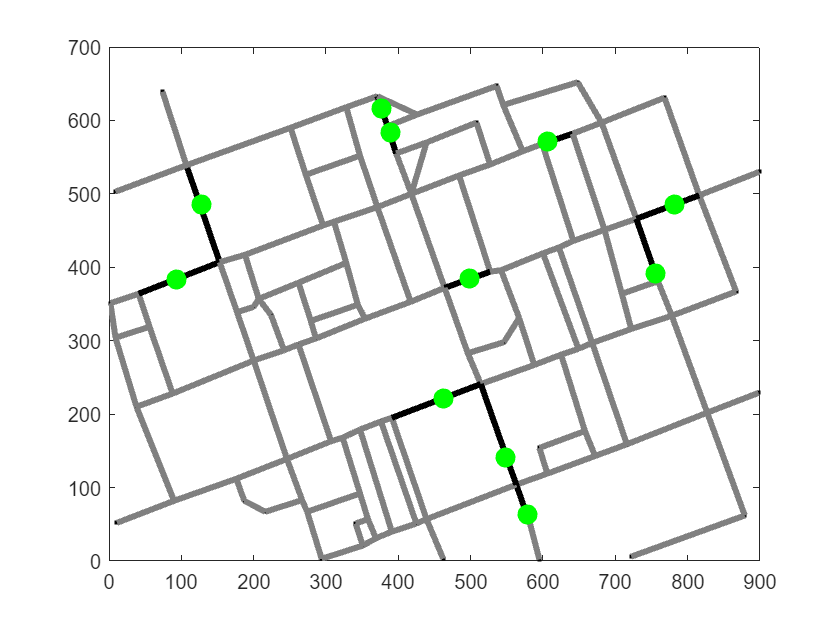

%% Find road segments containing sensors
n = length(xs) / 2;
midsx = (xs(1:2:end) + xs(2:2:end)) / 2;
midsy = (ys(1:2:end) + ys(2:2:end)) / 2;
nsens = length(sensx);
idsens = NaN(nsens, 1);

for i = 1:nsens
    dds = sqrt((midsx - sensx(i)).^2 + (midsy - sensy(i)).^2);
    if i == 9
        [~, oo] = sort(dds);
        idsens(i) = oo(2);
    else
        [~, idsens(i)] = min(dds);
    end
    %disp(idsens(i));
end

%% Plot the segments and sensor locations
% segments associated with sensors are highlighted in the plot
figure;
plot(xs, ys, 'k.');
hold on;
for i = 1:n
    if ismember(i, idsens)
        line([xs(2*i-1), xs(2*i)], [ys(2*i-1), ys(2*i)], 'Color', 'k', 'LineWidth', 3);
    else
        line([xs(2*i-1), xs(2*i)], [ys(2*i-1), ys(2*i)], 'Color', [0.5, 0.5, 0.5], 'LineWidth', 3);
    end
end
scatter(sensx, sensy, 100, 'g', 'filled');
hold off;


%% Merge sensors in the same location
signal = NaN(length(unique(idsens)), size(central, 2));
cc = 1;
c = 1;
while c <= length(unique(idsens))
    if sum(idsens == idsens(cc)) > 1
        signal(c, :) = central(cc, :) + central(cc+1, :);
        % add counts of sensors on the same street segments, as these are
        % typically on opposite sides of the road.
        cc = cc + 2;
        c = c + 1;
    else
        signal(c, :) = central(cc, :) * 2;
        % double the counts of sensors that do not share the street segment
        % with another sensor, as these usually cover only one side of the
        % road
        cc = cc + 1;
        c = c + 1;
    end
end
sensnodes = unique(idsens); % we're left with 11 sensors out of the original 13.

Note the simplifications we are making here when combining counts.In practice, this is something that should be discussed and validated. As an exercise, why do you think the sensor locations don't fall directly onto the street segment lines? Looking at a map of Melbourne could be instructive.

We now need to compute the shortest distances between all nodes (street segment midpoints) and all sensor locations.

%% Compute shortest paths between nodes and sensors
net = graph(A);
alldists2 = distances(net, sensnodes);

Finally, we are in a position to implement the interpolation, using the sensor counts at one time point to predict the count at a different location (at the same time point). We implement this in a separate matlab script (also available on Blackboard) 'IDWprediction.m' that is shown commented out below:

%% Predict counts using IDW interpolation
%function predicts = IDWprediction(nodes, counts, sensors, alldists)
%    n = length(nodes);
%    predicts = NaN(n, 1);
%    for i = 1:n
%        shortpaths = alldists(:, nodes(i));
%        ids = 1:length(sensors);
         % the following ensures that sensor counts are not used to predict
         % themselves...
%        if any(shortpaths == 0)
%            ids(shortpaths == 0) = [];
%        end
         % the following line is the inverse distance weighting formula
         % with an exponent of 2. This can be adapted to include additional
         % factors...
%        predicts(i) = sum(counts(ids) ./ shortpaths(ids).^2) / sum(1 ./ shortpaths(ids).^2);
%    end
%end

% to test the function, we will predict the count for node 7 (where a sensors is locations
% at time 100
IDWprediction(7, signal(:, 100), sensnodes, alldists2)

ans = 44.0455

% compare to ground truth from the sensor
signal(7,100)

ans = 48

% ... not a great prediction...

We can now test the predictive success of the interpolation function more systematically. For example, we can predict a number of time steps for a given focal nodes (here chosen to be one of the sensor nodes, so that we have a ground truth) to see if the patterns match qualitatively and quantitatively (you can look at different sensors by changing the value of 'focal'):

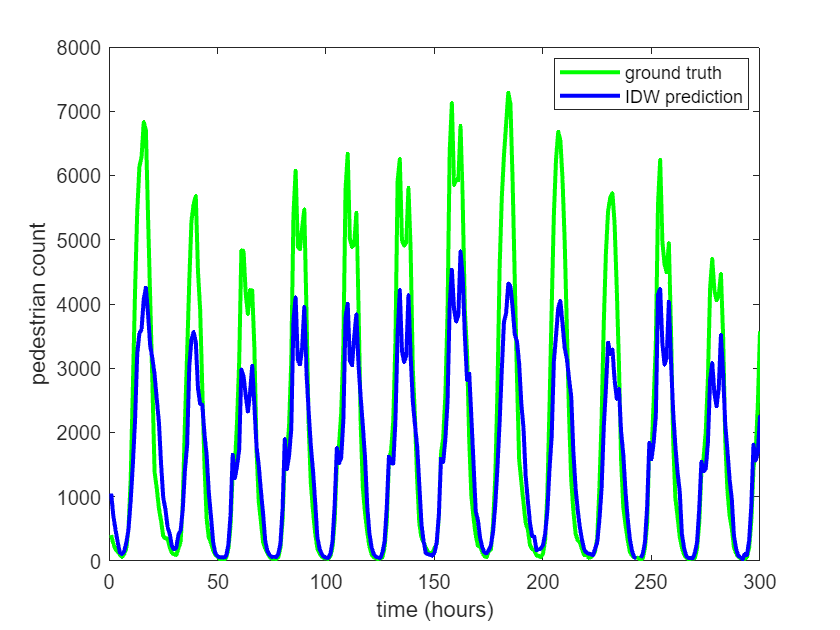

% Test the interpolation function more
focal = 9;
lala = zeros(1, 300);
for i = 1:300
    lala(i) = IDWprediction(sensnodes(focal), signal(:, i), sensnodes, alldists2);
end
figure;
plot(signal(focal,1:300), 'g', 'LineWidth', 2);
hold on;
plot(lala, 'b', 'LineWidth', 2);
ylim([0 8000]);
xlabel('time (hours)')
ylabel('pedestrian count')
% Add legend
legend('ground truth', 'IDW prediction', 'Location', 'Best');
hold off;

**Exercises**

**1.0. **How many parameters does this model have? (we didn't make this explicit in the code above)

**1.1.** Use inverse distance weighting to predict counts on the entire street network, and see how they change over time (you could create a video showing this).

% get predictions for all streets at a time t
noden = length(sensnodes);
times = 1:50;
preds = zeros(net.numnodes, length(times));

for t=times
    for i=1:net.numnodes
        preds(i, t) = IDWprediction(i, signal(:, t), sensnodes, alldists2);
    end
end

% normalise predictions between [0, 1] for colouring
predsnorm = (preds - min(preds));
predsnorm = predsnorm ./ max(predsnorm)

predsnorm =     0.0058         0    0.0423         0         0    0.1524    0.0276         0    0.2388    0.2387    0.1774    0.0741    0.0504    0.0240    0.0342    0.0546    0.0164         0         0         0         0         0         0         0    0.0401         0    0.0174         0    0.0177         0         0    0.0207    0.2946    0.4248    0.0478         0         0    0.0353    0.0136    0.0813    0.0861         0         0         0         0         0         0         0    0.0943    0.1335
    0.0511    0.0736    0.0826    0.0616    0.0569    0.2333    0.1014    0.0923    0.2891    0.2875    0.2359    0.1419    0.1280    0.1089    0.1161    0.1368    0.0982    0.1001    0.0814    0.0688    0.0572    0.0591    0.0670    0.0550    0.0884    0.0654    0.0742    0.0530    0.0617    0.0670    0.0955    0.0999    0.3523    0.4670    0.1328    0.0791    0.0913    0.1253    0.0990    0.1504    0.1553    0.0882    0.0906    0.0699    0.0669    0.0610    0.0654    0.0631    0.1

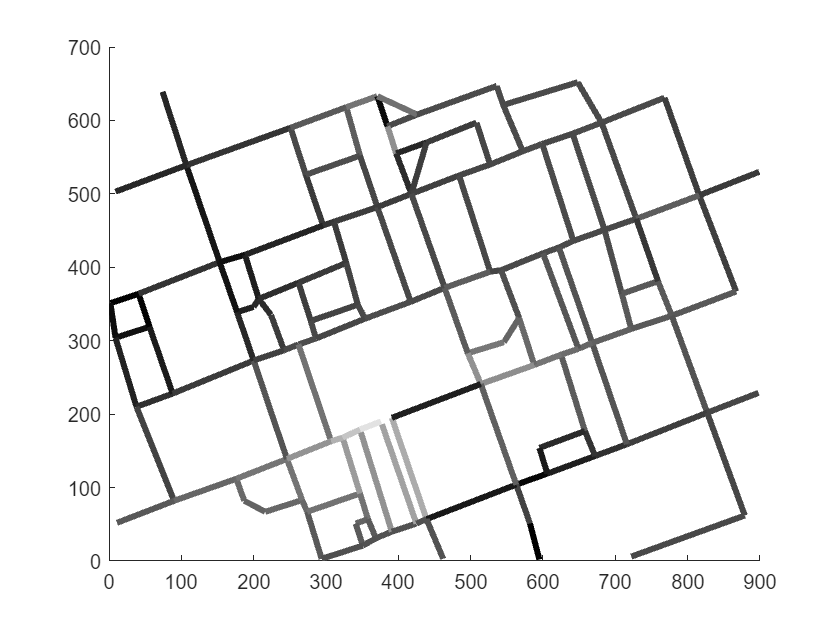


figure;
hold on;
for i=1:n
    colour = predsnorm(i, 1) .* [1, 1, 1];
    line([xs(2*i-1), xs(2*i)], [ys(2*i-1), ys(2*i)], 'Color', colour, 'LineWidth', 3);
end
hold off;

**1.2.** Discuss how prediction accuracy could be assessed more rigorously.

**1.3.** Extend the inverse distance weighting model. You should consider introducing additional variables that can be used in the calculation of distances between nodes (e.g., you could create artificial data on the width of pavements and include this in the distance calculation). You should also consider introducing free parameters that allow you to tune the contribution of sensors to the interpolation (discuss the implication of such an approach).

### 2. Time series modelling

In this example we will investigate the time series aspect of the pedestrian count data from Melbourne. To get a feel for the data, let's plot some of the time series:

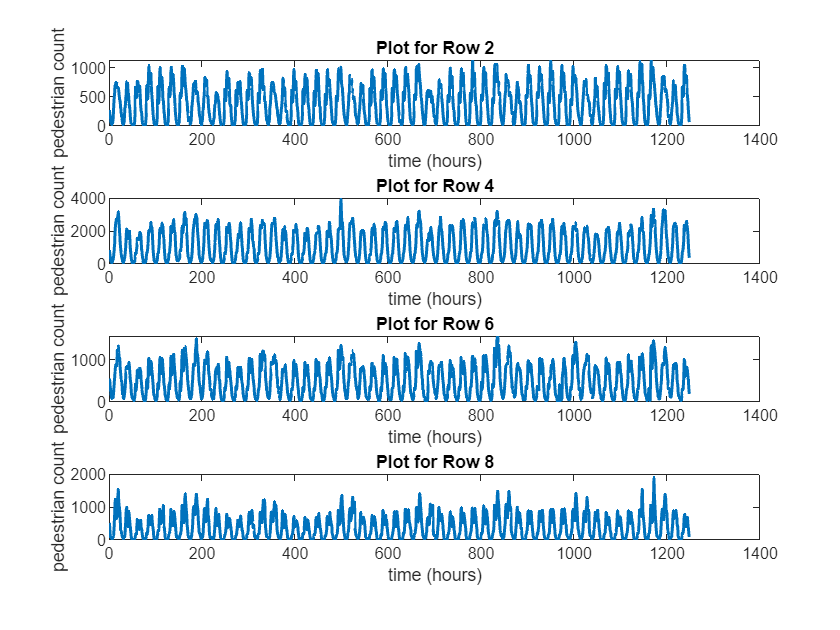

figure;

for i = 1:4
    subplot(4,1,i); % Create a 4x1 grid of subplots and select the i-th one
    plot(central(2*i, :), 'LineWidth', 1.5); % Plot the i-th row of central
    title(['Plot for Row ' num2str(2*i)]); % Title for each subplot
    xlabel('time (hours)');
    ylabel('pedestrian count');
end

... you should see daily and weekly patterns. If you look at the plots more closely (zooming in, or only plotting a subset of the time series), you should see more details of daily patterns, such as morning and afternoon peaks, and possibly lunchtime peaks.

Even with formal analysis, it is clear that the time series contain regular oscillatory patterns, and are highly auto-correlated.

In this section, we will cover the following topics:

- time series decomposition

- examples for ARIMA-style time series models

- an example for using machine learning for modelling a time series.

All these methods are fairly generic and widely used time series analysis methods. The transport context only really becomes apparent in the interpretation and discussion of the result we get from applying these methods to transport-related data.

For the remainder of this section, we will focus on the data from one of the sensors, but the methods shown obviously apply analogously to any time series.

First we, will use a simple additive time series decomposition to investigate the properties of the time series further.

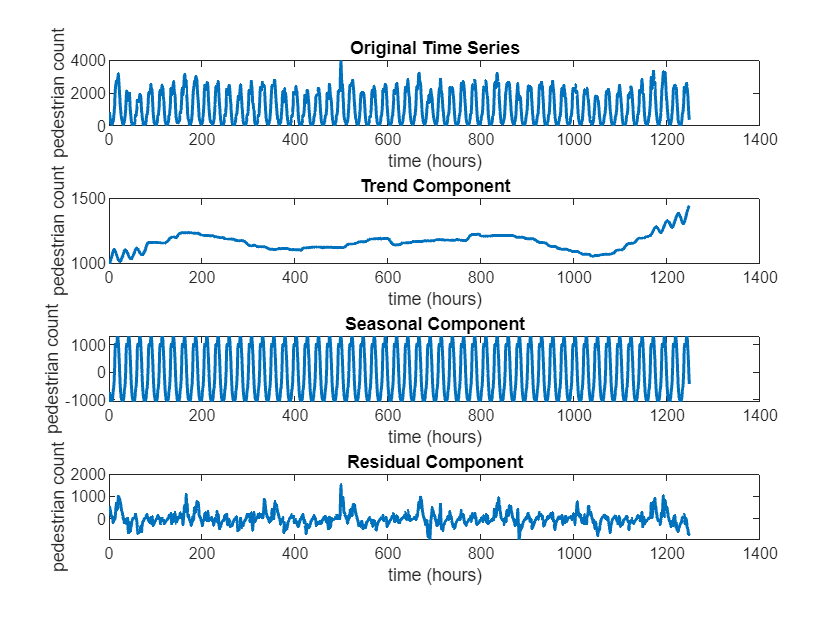

% select the time series from the data that we will use throughout this section:
timeseries = central(4,:);
n = length(timeseries);

% Plot the original time series
figure;
subplot(4,1,1);
plot(timeseries, 'LineWidth', 1.5);
title('Original Time Series');
xlabel('time (hours)');
ylabel('pedestrian count');

%% TREND COMPONENT
% Using a moving average filter to estimate the trend component
window_size = 24*7; % Adjust the window size for the moving average (e.g., weekly)
trend_component = movmean(timeseries, window_size);

% Subtract the trend component from the original series to get the detrended data
detrended = timeseries - trend_component;

% Plot the trend component
subplot(4,1,2);
plot(trend_component, 'LineWidth', 1.5);
title('Trend Component');
xlabel('time (hours)');
ylabel('pedestrian count');

%% SEASONAL COMPONENT
% Assuming the seasonality repeats every 'window_size2' (e.g., daily)
window_size2 = 24;
seasonal_component = detrended(1:window_size2); % First complete seasonal cycle
% compute average over all observed seasonal cycles:
for i = 2:ceil(n/window_size2)
    seasonal_component = seasonal_component + detrended(((i-1)*window_size2+1):(i*window_size2));
end
seasonal_component = seasonal_component/ceil(n/window_size2);
seasonal_component = repmat(seasonal_component, 1, ceil(n/window_size2));
%seasonal_component = seasonal_component(1:n); % Trim to match time series length
% Plot the seasonal component
subplot(4,1,3);
plot(seasonal_component, 'LineWidth', 1.5);
title('Seasonal Component');
xlabel('time (hours)');
ylabel('pedestrian count');

%% RESIDUAL (RANDOM) COMPONENT
residual_component = timeseries - trend_component - seasonal_component;

% Plot the residual component
subplot(4,1,4);
plot(residual_component, 'LineWidth', 1.5);
title('Residual Component');
xlabel('time (hours)');
ylabel('pedestrian count');


% As we have assumed an additive decomposition, the time series can be expressed as:
% timeseries = trend + seasonal + residual

This approach is not very sophisticated, and you will easily be able to find more advanced methods. However, it is very intuitive.

**Exercise 2.0:** play around with the window sizes used to define the trend/seasonal components and discuss how these patterns could arise in a transport context, and what additional patterns could be observed for the same or other transport modes, depending on the time of year, location, or other context.

Next, we will look at an example for fitting ARIMA-style models to the time series. We will start from the two most basic of these models to develop an intuitive understanding of how they work before fitting a more complex model to the data.

% Split the data into training and test sets (80% training, 20% test)
n = length(timeseries);
train_size = round(0.8 * n);
test_size = n - train_size;
train_data = timeseries(1:train_size);
test_data = timeseries(train_size+1:end);

% Plot the original time series
figure;
subplot(4,1,1);
plot(timeseries, 'LineWidth', 1.5);
title('Original Time Series');
xlabel('time (hours)');
ylabel('pedestrian count');

%% ARIMA(0,0,0) Model
% Fit an ARIMA(0,0,0) model to the training data
model_000 = arima(0, 0, 0);
fit_000 = estimate(model_000, train_data');

 
    ARIMA(0,0,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue   
                __________    _____________    __________    ___________

    Constant        1155.3       31.911          36.205      5.1552e-287
    Variance    8.6161e+05        72351          11.909       1.0645e-32




% Generate forecast from ARIMA(0,0,0) model
[forecast_000, ~] = forecast(fit_000, test_size, 'Y0', train_data');

% Plot ARIMA(0,0,0) forecast vs actual test data
subplot(4,1,2);
plot(train_size+1:n, test_data, 'k', 'LineWidth', 1.5); hold on;
plot(train_size+1:n, forecast_000, 'r', 'LineWidth', 1.5);
title('ARIMA(0,0,0) Model vs Actual Test Data');
xlabel('time (hours)');
ylabel('pedestrian count');
legend('Actual', 'Forecast');

You can see that the ARIMA(0,0,0), or AR(0) model only estimates the mean and variance of the time series. As such, it cannot capture any of the temporal patterns in the time series. The forecast shown in the plot above only indicates the mean. A different way to view the predictions of this model is to view them as samples from the Normal probability distribution specified by the mean and variance estimated by the model. As these samples are uncorrelated, repeated sampling would give rise to a time series with constant power spectral density, which is the definition for White noise.

We now include a first order autoregressive term:

%% ARIMA(1,0,0) Model
% Fit an ARIMA(1,0,0) model to the training data
model_100 = arima(1, 0, 0);
fit_100 = estimate(model_100, train_data');

 
    ARIMA(1,0,0) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue   
                _______    _____________    __________    ___________

    Constant     68.742        24.764         2.7758        0.0055059
    AR{1}       0.94163      0.014574         64.609                0
    Variance      98838        4090.1         24.165      5.1836e-129




% Generate forecast from ARIMA(1,0,0) model
[forecast_100, ~] = forecast(fit_100, test_size, 'Y0', train_data');

% Plot ARIMA(1,0,0) forecast vs actual test data
subplot(4,1,3);
plot(train_size+1:n, test_data, 'k', 'LineWidth', 1.5); hold on;
plot(train_size+1:n, forecast_100, 'b', 'LineWidth', 1.5);
title('ARIMA(1,0,0) Model vs Actual Test Data');
xlabel('time (hours)');
ylabel('pedestrian count');
legend('Actual', 'Forecast');

The ARIMA(1,0,0) or AR(1) model estimates an first order autoregressive term as well as mean and variance. The forecast shown above looks very unimpressive. This is because we ask the model to forecast 250 hours into the future. This is also called "Closed loop forecasting". The model uses the information from the hour preceding the start of the test data. As the autoregressive term is estimated to be below 1 and because the value of this hour used in predictions is above the mean, you can see that the forecast gradually decreases towards the mean. Changing the time period over which we want to forecast shows the functioning of this model more clearly (see below). As for the AR(0) model, the forecast shown is only the mean. The model, being a statistical model, actually predicts that values lie within a distribution around this mean.

For most applications, we have to consider more complex models. For example, time series that include longer-term trends usually require one or more orders of differencing, and regular recurring patterns can also be modelled explicitly. We will look at this now.

Next, we will take a look at a SARIMA model that enables us to capture seasonal, i.e. regularly occurring, patterns.

%% SARIMA Model
model_sarima = arima('D',1,'Seasonality',24);
% we have chosen the time period over which seasonality occures, here 24
% hours.
fit_sarima = estimate(model_sarima, train_data');

 
    ARIMA(0,1,0) Model Seasonally Integrated (Gaussian Distribution):
 
                 Value      StandardError    TStatistic    PValue 
                ________    _____________    __________    _______

    Constant    -0.12539       6.2305        -0.020124     0.98394
    Variance       37732       930.61           40.546           0



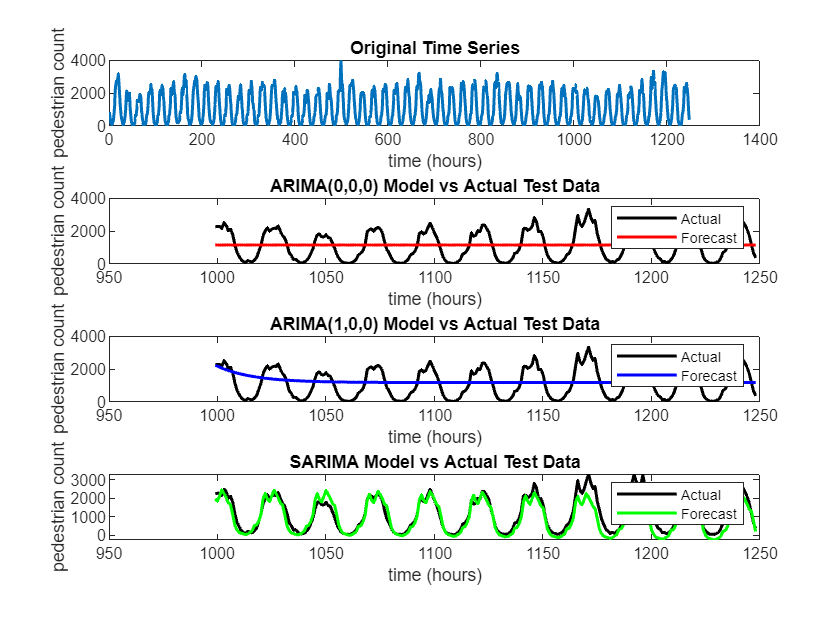


% Generate forecast from the SARIMA model
[forecast_sarima, ~] = forecast(fit_sarima, test_size, 'Y0', train_data');

% Plot SARIMA forecast vs actual test data
subplot(4,1,4);
plot(train_size+1:n, test_data, 'k', 'LineWidth', 1.5); hold on;
plot(train_size+1:n, forecast_sarima, 'g', 'LineWidth', 1.5);
title('SARIMA Model vs Actual Test Data');
xlabel('time (hours)');
ylabel('pedestrian count');
legend('Actual', 'Forecast');


%% Accuracy Comparison using the Root Mean Square Error (RMSE)
% Calculate RMSE for each model
rmse_000 = sqrt(mean((test_data - forecast_000').^2));
rmse_100 = sqrt(mean((test_data - forecast_100').^2));
rmse_sarima = sqrt(mean((test_data - forecast_sarima').^2));

% Display RMSE values
fprintf('RMSE for ARIMA(0,0,0): %.2f\n', rmse_000);

RMSE for ARIMA(0,0,0): 927.38


fprintf('RMSE for ARIMA(1,0,0): %.2f\n', rmse_100);

RMSE for ARIMA(1,0,0): 928.38


fprintf('RMSE for SARIMA: %.2f\n', rmse_sarima);

RMSE for SARIMA: 415.99


The forecast plot shows that SARIMA can successfully capture the regular daily patterns in our data. Comparing RMSE scores for the three models shows that SARIMA performs best.

**Exercise 2.1**: can you make a case for choosing different time intervals for the seasonality? Try this out in the code.

**Exercise 2.2**: change the structure of the ARIMA models to explore how this affects model forecats behaviour (e.g. by including higher-order auto-regressive terms, or similar).

As mentioned below, when predicting over long time periods, we are making big demands on our models. To further demonstrate the working of the different models, we now produce model forecasts by only predicting one step into the future at every time-step, making use of the observed data at the previous time step. This is also called "Open loop forecasting".

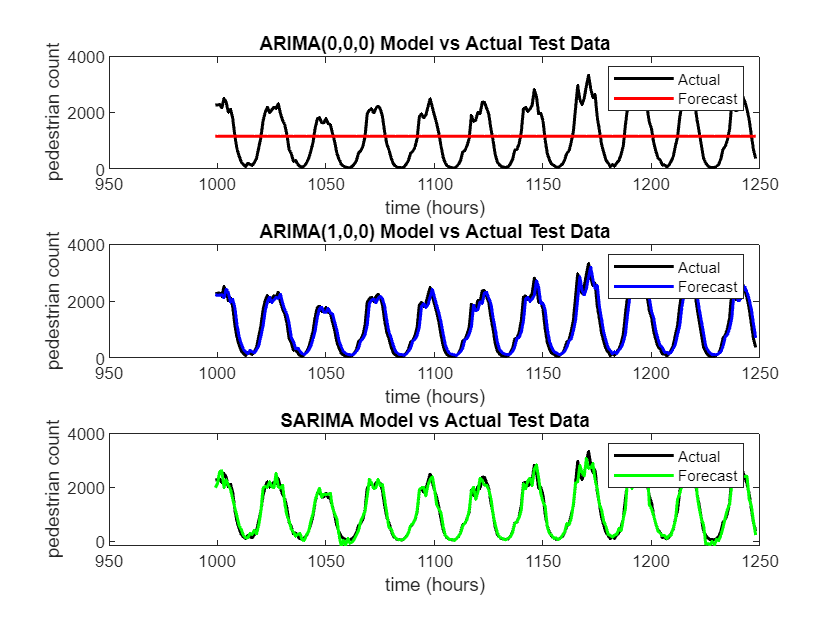

%% recalculate the model forecasts

% prepare data to be used in forecasting (note how we now use the test data):
data_for_forecasts = [train_data(length(train_data)), test_data];
% the SARIMA model needs more than one previous time step...
data_for_forecasts2 = [train_data((length(train_data)-24):length(train_data)), test_data];

for i = 1:test_size
    forecast_000(i) = forecast(fit_000, 1, data_for_forecasts(i));
    forecast_100(i) = forecast(fit_100, 1, data_for_forecasts(i));
    forecast_sarima(i) = forecast(fit_sarima, 1, data_for_forecasts2(i:(i+24))');
end

%% Plotting
figure;
% Plot ARIMA(0,0,0) forecast vs actual test data
subplot(3,1,1);
plot(train_size+1:n, test_data, 'k', 'LineWidth', 1.5); hold on;
plot(train_size+1:n, forecast_000, 'r', 'LineWidth', 1.5);
title('ARIMA(0,0,0) Model vs Actual Test Data');
xlabel('time (hours)');
ylabel('pedestrian count');
legend('Actual', 'Forecast');
% Plot ARIMA(1,0,0) forecast vs actual test data
subplot(3,1,2);
plot(train_size+1:n, test_data, 'k', 'LineWidth', 1.5); hold on;
plot(train_size+1:n, forecast_100, 'b', 'LineWidth', 1.5);
title('ARIMA(1,0,0) Model vs Actual Test Data');
xlabel('time (hours)');
ylabel('pedestrian count');
legend('Actual', 'Forecast');
% Plot SARIMA forecast vs actual test data
subplot(3,1,3);
plot(train_size+1:n, test_data, 'k', 'LineWidth', 1.5); hold on;
plot(train_size+1:n, forecast_sarima, 'g', 'LineWidth', 1.5);
title('SARIMA Model vs Actual Test Data');
xlabel('time (hours)');
ylabel('pedestrian count');
legend('Actual', 'Forecast');


%% Accuracy Comparison (RMSE)
% Calculate RMSE for each model
rmse_000 = sqrt(mean((test_data - forecast_000').^2));
rmse_100 = sqrt(mean((test_data - forecast_100').^2));
rmse_sarima = sqrt(mean((test_data - forecast_sarima').^2));

% Display RMSE values
fprintf('RMSE for ARIMA(0,0,0): %.2f\n', rmse_000);

RMSE for ARIMA(0,0,0): 927.38


fprintf('RMSE for ARIMA(1,0,0): %.2f\n', rmse_100);

RMSE for ARIMA(1,0,0): 303.60


fprintf('RMSE for SARIMA: %.2f\n', rmse_sarima);

RMSE for SARIMA: 220.39


You can see that the AR(0) model forecast does not change, as it does not include autoregressive terms. The AR(1) forecast now tracks the time series very closely. However, if you zoom in on the plot, you will see that the forecast follows the time series with a lag of one hour, as is to be expected when the model only depends on a mean and the value of the previous time step. Finally, the SARIMA model captures the time series even better now than before. A look at the RMSE scores confirms this. The improvement in all models except AR(0) should not come as a surprise because we provide them with substantially more data, and the prediction horizon is reduced.

The two examples for different prediction horizons also suggest that the way models are evaluated will depend on their intended use. In most circumstances, simply reporting RMSE scores for a fixed portion of the time series is not enough.

Finally, we will use a well-estbalished machine learning approach for modelling the data, the Long short-term memory (LSTM) recurrent neural network. We will perform Open loop forecasting.

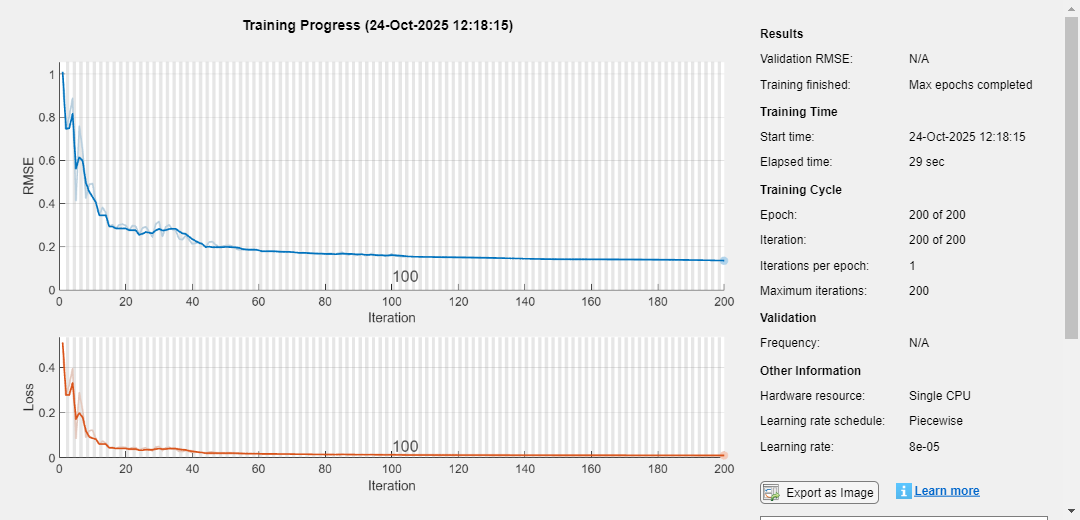

% we use the same training and test data as before.

% Prepare data for LSTM, including normalisation to zero mean and unit
% standard deviation
XTrain = train_data(1:(train_size-1));
muX = mean(XTrain);
sdX = std(XTrain);
XTrain = (XTrain-muX) ./ sdX;
YTrain = train_data(2:train_size);
muY = mean(YTrain);
sdY = std(YTrain);
YTrain = (YTrain-muY) ./ sdY;

% Define LSTM network architecture
numFeatures = 1;
numHiddenUnits = 100; % Number of LSTM hidden units
numResponses = 1;
%sequenceLength = 1; % Since we are predicting the next time step

% defining the structure of the LSTM here.
% I include two LSTM layers - this is something that can/should be
% investigated more carefully.
layers = [ ...
    sequenceInputLayer(numFeatures, 'Name', 'input')
    lstmLayer(numHiddenUnits, 'OutputMode', 'sequence', 'Name', 'lstm1')
    lstmLayer(numHiddenUnits, 'OutputMode', 'sequence', 'Name', 'lstm2')
    fullyConnectedLayer(numResponses, 'Name', 'fc')
    regressionLayer('Name', 'output')];

% Define training options
options = trainingOptions('adam', ...
    'MaxEpochs', 200, ...
    'GradientThreshold', 0.1, ...
    'InitialLearnRate', 0.01, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 50, ...
    'LearnRateDropFactor', 0.2, ...
    'Verbose', 0, ...
    'Shuffle','never',...
    'Plots', 'training-progress');

% Train the LSTM network
net = trainNetwork(XTrain, YTrain, layers, options);

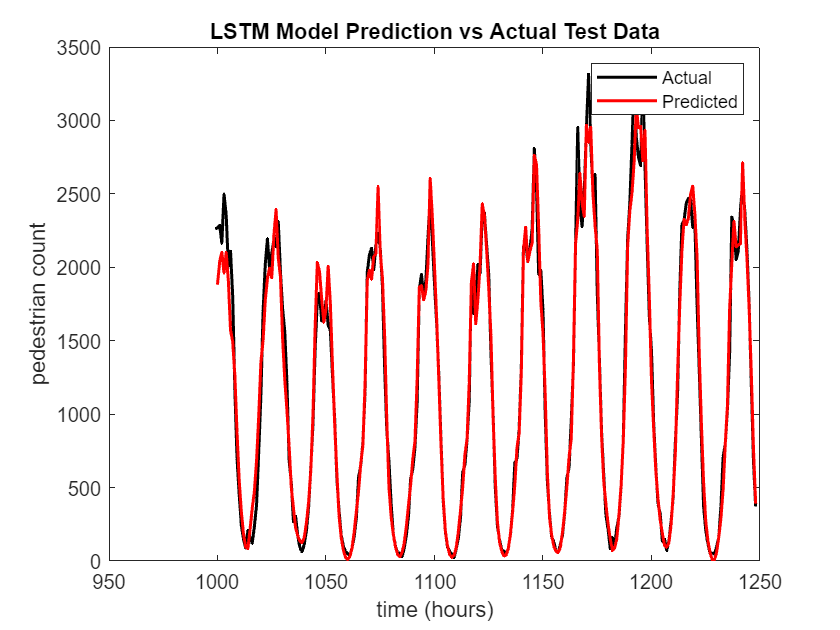


% Prepare test data
XTest =(test_data(1:(test_size-1))-muX) ./ sdX;
YTest = test_data(2:test_size);

% Predict using the trained LSTM model making sure to undo the
% normalisation
YPred = sdY*predict(net, XTest)+muY;
% for closed loop forecasting, we would have to create a loop that would
% make initial predictions using true data, and then append these
% predictions to our time series.

% Calculate RMSE for evaluation
rmse = sqrt(mean((YTest - YPred).^2));

% Plot the actual vs. predicted values
figure;
plot(train_size+1:n, test_data, 'k', 'LineWidth', 1.5); hold on;
plot(train_size+2:n, YPred, 'r', 'LineWidth', 1.5);
title('LSTM Model Prediction vs Actual Test Data');
xlabel('time (hours)');
ylabel('pedestrian count');
legend('Actual', 'Predicted');
hold off;


% Display RMSE value
fprintf('RMSE for LSTM Model: %.2f\n', rmse);

RMSE for LSTM Model: 154.71


Even without much tuning of the LSTM setup, it performs well. This comes at the expense of not having direct insights into the structure of the model, such as the auto-regressive order used. Nevertheless, for short-term forecasting problems of transportation time-series, machine-learning techniques (including LSTMs but also others) are currently the most commonly used approach.

**Exercises**

**2.3.** implement closed loop forecasting for LSTM example.

**2.4.** try adding additional extraneous predictors to the models (e.g. information on when bank holidays are, or weather data - as I haven't given you this data, simulate it if you would like to try out some code).

**2.5.** discuss/reflect on more robust ways of comparing the different models that go beyond calculating RMSE values for a fixed test set.

**2.6.** use a time series model of your choice to compare the time series at different locations (recall that we have focussed on one location above, for convenience).

**2.7.** implement an alternatice time series model, different to the ones discuss here.

### 3. Machine-learning a microscopic model

In this final example, we will develop a simple machine learning model for predicting the microscopic movements of pedestrians.

We will use trajectory data of people leaving a room through one exit, you can find the original data here: [https://doi.org/10.34735/ped.2006.2](https://doi.org/10.34735/ped.2006.2) and the data we use in this example is on Blackboard.

Our general approach will be as follows:

- preprocess data by discretising trajectories onto a grid

- parcel the data into input and output grids that only consider the immediate neighbourhood of a pedestrian (input) whose next position (output) we wish to predict in a similar way to what was discussed in lecture 3 of the data-driven modelling topic

- generate test and training data

- train a simple neural network

- look at the results

Let's start by reading in the data and doing some preprocessing:

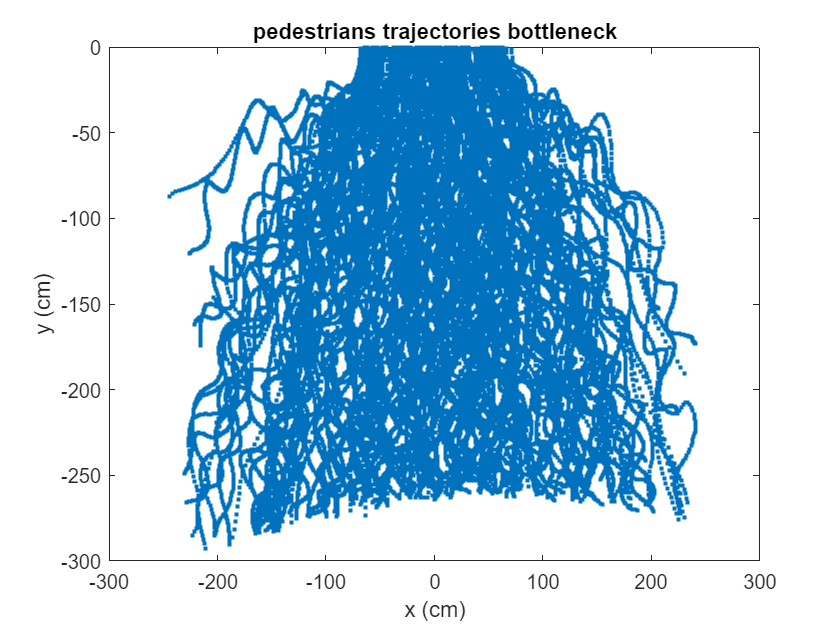

% Load data
data = load('b160_combined.txt');

% Remove bottleneck data
data(data(:, 4) > 0, :) = [];
nn = size(data, 1);

% plot the trajectories
figure;
plot(data(:,3),data(:,4),'.');
title('pedestrians trajectories bottleneck');
xlabel('x (cm)');
ylabel('y (cm)');
hold off;

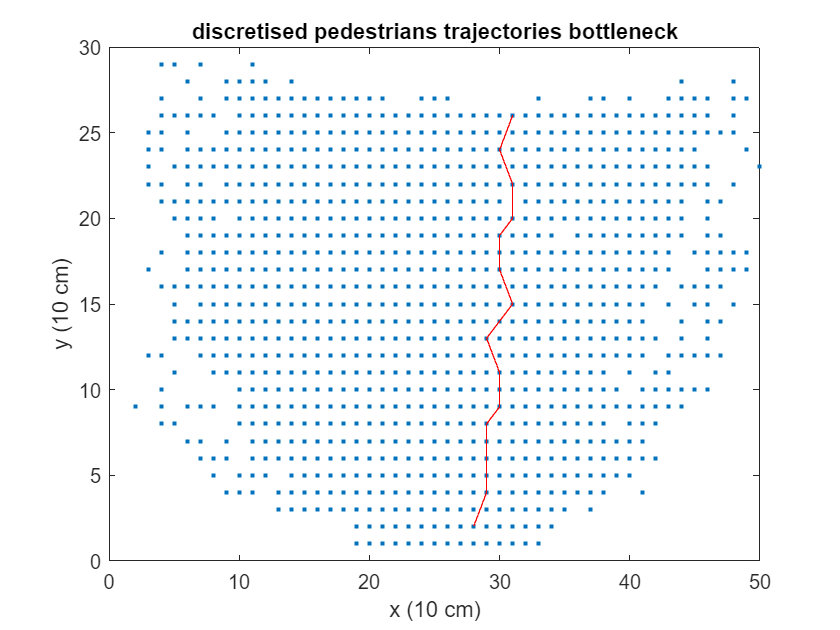


% Get unique IDs and times
ids = unique(data(:, 1));
times = unique(data(:, 2));

% Function to discretize coordinates onto a grid of 10 cm x 10 cm cells
getcoord = @(x, y) [floor((x + 250) / 10) + 1, floor(abs(y) / 10) + 1];

% Apply discretization
datanew = data;
for k = 1:nn
    datanew(k, 3:4) = getcoord(data(k, 3), data(k, 4));
end

% Downsample the frame rate from 10Hz to 2Hz
% we do this, so that pedestrians move at a reasonable speed given the size
% of grid cells we are using
timesnew = min(times):10:max(times);
inn = ismember(datanew(:, 2), timesnew);
datanew = datanew(inn, :);
nnew = size(datanew, 1);

% plot the discretised positions and one trajectory example
figure;
plot(datanew(:,3),datanew(:,4),'.');
title('discretised pedestrians trajectories bottleneck');
hold on
person = randsample(ids, 1);
traj = datanew(datanew(:, 1) == person, 3:4);
plot(traj(:, 1), traj(:, 2), 'LineWidth', 0.5, 'Color', 'red');
xlabel('x (10 cm)');
ylabel('y (10 cm)');
hold off;

Data parceling is implemented in the separate matlab script 'dataparcel.m' that you can download from Blackboard. We will now use this to create test and training data:

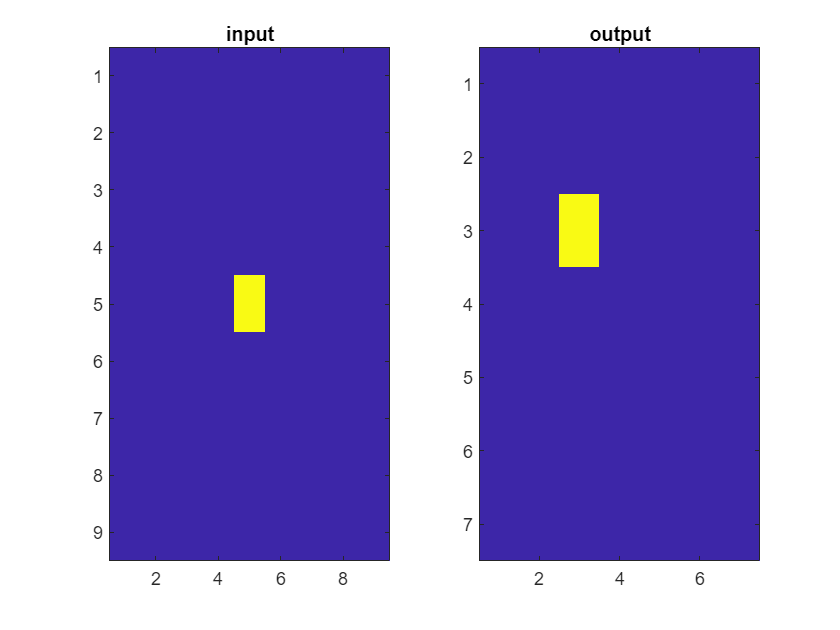

% Let's look at how the data parceling works:
% we randomly select the data we look at here, so you may have to run this
% code a few times to get a feel for the different situation that can
% happen.
[input, output, currpos] = dataparcel(randsample(ids, 1), datanew);

inmat = reshape(input, 9, 9);
outmat = reshape(output, 7, 7);
figure;
subplot(1,2,1);
imagesc(inmat);
title('input');
% the input captures the positions of all pedestrians around the selected
% pedestrian, including the selected pedestrian's position in the centre of
% the grid
hold on
subplot(1,2,2);
imagesc(outmat);
title('output');
% the output shows the new position of the selected pedestrian after one
% time step has passed - the original position of the pedestrian is in the
% centre of the grid
hold off


% Training data
NX = 4000;
X_train = zeros(81, NX);
y_train = zeros(49, NX);

for o = 1:NX
    [input, output, ~] = dataparcel(randsample(ids, 1), datanew);
    X_train(:, o) = input;
    y_train(:, o) = output;
end

% Testing data
NX_test = 1000;
X_test = zeros(81, NX_test);
y_test = zeros(49, NX_test);

for o = 1:NX_test
    [input, output, ~] = dataparcel(randsample(ids, 1), datanew);
    X_test(:, o) = input;
    y_test(:, o) = output;
end

**Exercise 3.0:** this is probably not the best way of constructing test and training data. Why?

Now we implement the machine learning model. We have discretised input and output, and basic idea we adopt here is to frame the predictions as a classification problem.

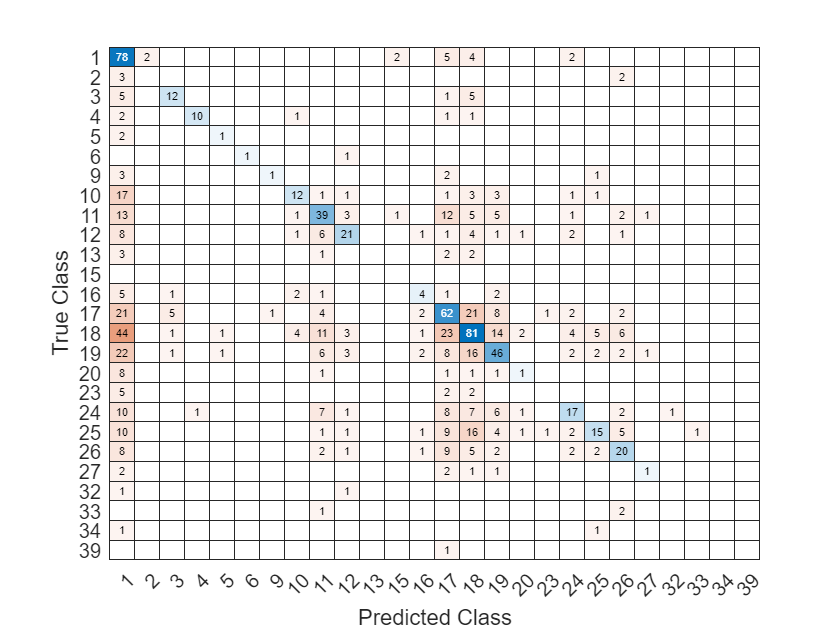

% Convert data format for MATLAB neural network
% Convert y_train into categorical labels - we will frame this as a
% classification problem
% each of the 49 cells of the output matrix we are using could be a
% category but since not all categories are observed, there are fewer than
% 49 categories
y_train_categorical = vec2ind(y_train)';

% Train a neural network using fitcnet
Mdl = fitcnet(X_train', y_train_categorical, 'LayerSizes', [100], 'Activations', 'relu', 'Standardize', true);


% Predict on the test set
y_pred = predict(Mdl, X_test');

% Compare predictions and ground truth
% you may have to zoom in on this confusion matrix
y_test_categorical = vec2ind(y_test)';
figure;
confusionchart(y_test_categorical, y_pred);

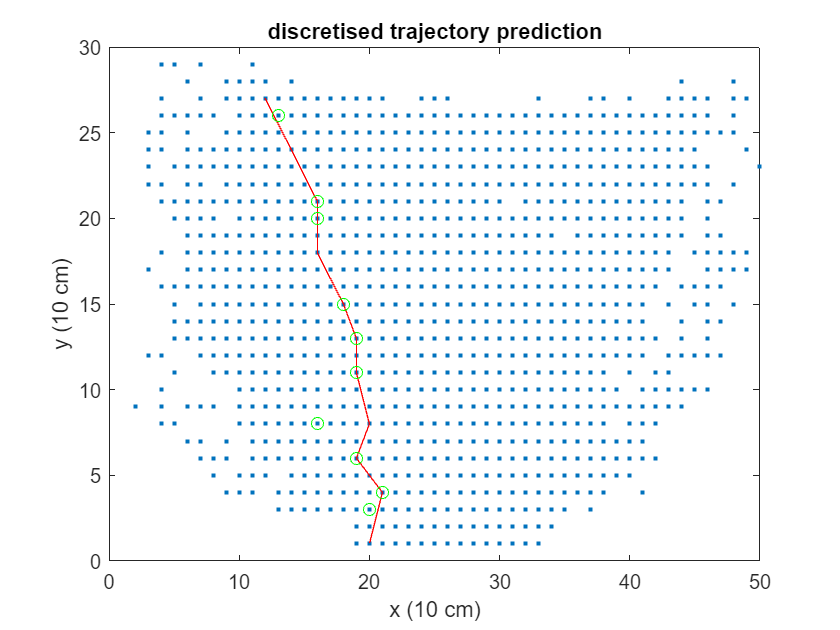



% plot the predicted positions for one trajectory example
figure;
plot(datanew(:,3),datanew(:,4),'.');
title('discretised trajectory prediction');
hold on
person = randsample(ids, 1);
traj = datanew(datanew(:, 1) == person, 3:4);
plot(traj(:, 1), traj(:, 2), 'LineWidth', 0.5, 'Color', 'red');
% predicted trajectory
% Testing data
Npred = size(traj,1)*5;
% ...because we sample time points in dataparcel(), we'll predict more
% positions than would strictly be needed (these will include several
% copies of the same positions...)
Xpred = zeros(81, Npred);
ypred = zeros(49, Npred);
currpos = zeros(2, Npred);
predpos = zeros(2, Npred);
for o = 1:Npred
    [input, output, tmp] = dataparcel(person, datanew);
    Xpred(:, o) = input;
    ypred(:, o) = output;
    currpos(:, o) = tmp;
end
% predict positions:
ypred2 = predict(Mdl, Xpred');
% Convert predictions back to binary matrix and use these to find predicted
% grid position:
ypred_bin = zeros(size(ypred'));
for u = 1:size(ypred_bin, 1)
    iidx = ypred2(u, :);
    ypred_bin(u, iidx) = 1;
    xdiff = rem(iidx,7);
    if xdiff==0
        xdiff = 7;
        ydiff = floor(iidx/7);
    else
        ydiff = floor(iidx/7)+1;
    end
    xdiff = xdiff - 4;
    ydiff = ydiff - 4;
    predpos(1,u) = currpos(1,u)+xdiff;
    predpos(2,u) = currpos(2,u)+ydiff;
end
plot(predpos(1,:), predpos(2,:), 'o', 'Color', 'green');
xlabel('x (10 cm)');
ylabel('y (10 cm)');
hold off;

% the green circles show predicted positions
% quite a few of them do not fall onto the true trajectory shown in red,
% suggesting a mismatch between predictions and ground truth

This is a simple, perhaps even simplistic approach to constructing a machine learning model for microscopic pedestrian movements. There are substantially better models but this is still an active areas of research. The purpose of this example is to introduce the principle of this data-driven modelling approach in a tractable way.

**Exercises:**

**3.1.** discuss how the confusion matrix can be interpreted.

**3.2.** list limitations/poor design choices of the approach shown above.

**3.3.** try to improve the model.